# Trasformata e antitrasformata di Laplace

## Setup

close all;
clear all;
clc;

## Variabili simboliche

% Tempo
syms t
% Funzione del tempo
syms f

% Variabile complessa
syms s
% Funzione della variabile complessa
syms F

% Parametri
% Traslazione temporale 
syms T positive
% Fattore esponenziale
syms a
% Pulsazione
syms w

## Trasformata di Laplace

### Impulso

f(t) = dirac(t);
disp('L[delta(t)]:')
F(s) = laplace(f);
pretty(F(s))

### Gradino

f(t) = heaviside(t);
disp('L[1(t)]:')
F(s) = laplace(f);
pretty(F(s))

### Rampa lineare

f(t) = t;
disp('L[t]:')
F(s) = laplace(f);
pretty(F(s))

### Esponenziale

f(t) = exp(a*t);
disp('L[exp(at)]:')
F(s) = laplace(f);
pretty(F(s))

### Seno

f(t) = sin(w*t);
disp('L[sin(wt)]:')
F(s) = laplace(f);
pretty(F(s))

### Coseno

f(t) = cos(w*t);
disp('L[cos(wt)]:')
F(s) = laplace(f);
pretty(F(s))

## Trasformata della traslazione temporale

### Traslazione di un gradino

f(t) = heaviside(t);
disp('L[1(t-T)]:')

L[1(t-T)]:


F(s) = laplace(f(t-T));
pretty(F(s))

exp(-T s)
---------
    s



### Traslazione di un'esponenziale

f(t) = exp(a*t) * heaviside(t);
disp('L[exp(a(t-T))1(t-T)]:')

L[exp(a(t-T))1(t-T)]:


F(s) = laplace(f(t-T));
pretty(F(s))

  exp(-T s)
- ---------
    a - s



### Traslazione di una sinusoide

f(t) = sin(w*t) * heaviside(t);
disp('L[sin(w(t-T))1(t-T)]:')

L[sin(w(t-T))1(t-T)]:


F(s) = simplify(laplace(f(t-T)));
pretty(F(s))

w exp(-T s)
-----------
   2    2
  s  + w



## Antitrasformata

### Antitrasformata semplice

F(s) = w / (s^2 + w^2);
disp('L^{-1}[w / (s^2 + w^2)]:')

L^{-1}[w / (s^2 + w^2)]:


f(t) = ilaplace(F);
pretty(f(t))

sin(t w)



### Traslazione nella trasformata

disp('L^{-1}[w / ((s - a)^2 + w^2)]:')

L^{-1}[w / ((s - a)^2 + w^2)]:


f(t) = ilaplace(F(s-a));
pretty(f(t))

exp(a t) sin(t w)



#### Traslazione della trasformata del coseno

F(s) = s / (s^2 + w^2);
disp('L^{-1}[(s - a) / ((s - a)^2 + w^2)]:')

L^{-1}[(s - a) / ((s - a)^2 + w^2)]:


f(t) = simplify(ilaplace(F(s-a)));
pretty(f(t));

exp(a t) cos(t w)



## Grafico

### Scelta dei parametri

% Scegliere i valori per "a" e "w"
aa = -1;
freq = 1;
ww = 2*pi*freq;

### Grafico

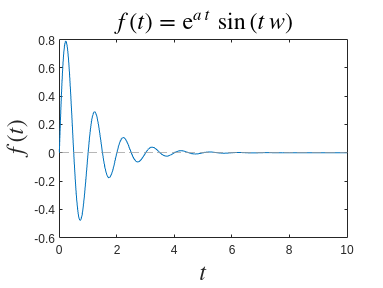

% Definire l'asse temporale
tt = linspace(0, 10, 1000);

% Graficare
plot(t, subs(f(t), [a w], [aa ww]));
xlabel('$$t$$', 'interpreter','latex', 'FontSize',20)
ylabel('$$f(t)$$', 'Interpreter','latex', 'FontSize',20)
yline(0, '--', 'LineWidth',0.5, 'Color',[0.6 0.6 0.6])
title(['$$f(t) = ' latex(f) '$$'], 'Interpreter','latex', 'FontSize',20)